# Initialize

close all;
clear variables; 
global n_plot
init_FB();

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 1e4; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency  

### Filter-bank properties

Qi          = 3000;%Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0; 
S           = 1; % Oversampling

f0_min      = 220e9;
f0_max      = 2*f0_min;
nFilters    = floor( 1 + log10(f0_max / f0_min) / log10(1 + 1 ./ Ql_target ./ S) );

f0          = zeros(1,nFilters);
f0(1)       = f0_min;

for filter_i=2:nFilters
   f0(filter_i) = f0(filter_i-1) + f0(filter_i-1) * 1 ./ Ql_target ./ S;
end
f0 = sort(f0,'descend');

% TL-Impedances
Z0_KID      = 54.81;
Z0_thru     = 79.04;



singleFilterPlot = nFilters;

% SET SETTINGS
Settings.singleFilterPlot = nFilters; 
Settings.Z0_thru = Z0_thru;
Settings.Z0_KID = Z0_KID;
Settings.Qi = Qi;
Settings.ThruLineLosses = ThruLineLosses;
Settings.sep = sep;
Settings.f0 = f0;
Settings.Ql_target = Ql_target;

### Loop

n_loops = 20;

for iter = 1:n_loops
    n_plot = 0;



### Variances

    %% Ql %%
    Ql_sigma = 0.2 ; % Variance of Ql, normalized to 1
    
    %% f0 %%
    f0_sigma = 0;%0.27;% .* Ql_target ./ 500; % Relative variance of f0 (df), normalized to 1. 
    f0_drift = 0; % linear drift of f0
    f0_offset = 0; % additive offset of f0
    
    % Lower bound on Ql_scattered, based on analysis of Deshima II by Akira
    Ql_min_thresh = -1.5 .* Ql_target .* Ql_sigma;
    
    
    
    num_elem = 4; 
    Ql_variance = zeros(num_elem,nFilters);
    f0_variance = zeros(num_elem,nFilters);
    
    interFilterVariance = true;
    
    
    if interFilterVariance
        
%         Ql_sigma = Ql_sigma ./ sqrt(2);
%         f0_sigma = f0_sigma ./ sqrt(2);
    
        for i_elem = 1:num_elem %#ok<*UNRCH> 
            
            %%%% Scattered design parameters %%%%
            Ql_variance(i_elem,:) = Ql_target .* Ql_sigma .* randn(1,nFilters);
            Ql_variance(i_elem,Ql_variance(i_elem,:) < Ql_min_thresh) = Ql_min_thresh;
            df = f0 ./ Ql_target;
            f0_variance(i_elem,:) = df .* f0_sigma .* randn(1,nFilters);
        end
    else
        
        %%%% Scattered design parameters %%%%
        Ql_variance = repmat(Ql_target .* Ql_sigma .* randn(1,nFilters),4,1);
        Ql_variance(Ql_variance < Ql_min_thresh) = Ql_min_thresh;
        df = f0 ./ Ql_target;
        f0_variance = repmat(df .* f0_sigma .* randn(1,nFilters),4,1);
    end
    
    Settings.f0_variance = f0_variance;
    Settings.Ql_variance = Ql_variance;

# Filterbanks

## Directional filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceDirectionalFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 76.207293 seconds


Section took 4.483534 seconds


Section took 4.148246 seconds


Section took 4.141670 seconds


Section took 4.492483 seconds


Section took 4.286374 seconds


Section took 4.270526 seconds


Section took 4.276136 seconds


Section took 4.395832 seconds


Section took 4.321581 seconds


Section took 4.364212 seconds


Section took 4.250688 seconds


Section took 4.324907 seconds


Section took 4.348348 seconds


Section took 4.215891 seconds


Section took 4.374917 seconds


Section took 4.288087 seconds


Section took 4.968365 seconds


Section took 4.253565 seconds


Section took 4.512565 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_dir(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.491319 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.86
Section took 0.492974 seconds


Section took 1.375134 seconds
Usable Spectral Fraction old = 0.93
Usable Spectral Fraction half mean envelope = 0.86
Section took 0.454392 seconds


Section took 1.229259 seconds
Usable Spectral Fraction old = 0.91
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.445973 seconds


Section took 1.225599 seconds
Usable Spectral Fraction old = 0.94
Usable Spectral Fraction half mean envelope = 0.84
Section took 0.426073 seconds


Section took 1.334766 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.81
Section took 0.461318 seconds


Section took 1.352000 seconds
Usable Spectral Fraction old = 0.94
Usable Spectral Fraction half mean envelope = 0.81
Section took 0.421556 seconds


Section took 1.246303 seconds
Usable Spectral Fraction old = 0.93
Usable Spectral Fraction half mean envelope = 0.82
Section took 0.457826 seconds


Section took 1.234645 seconds
Usable Spectral Fraction old = 0.93
Usable Spectral Fraction half mean envelope = 0.84
Section took 0.431049 seconds


Section took 1.223592 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.82
Section took 0.448681 seconds


Section took 1.355342 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.455890 seconds


Section took 1.254585 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.84
Section took 0.442355 seconds


Section took 1.226929 seconds
Usable Spectral Fraction old = 0.93
Usable Spectral Fraction half mean envelope = 0.84
Section took 0.425544 seconds


Section took 1.256902 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.84
Section took 0.426317 seconds


Section took 1.268255 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.82
Section took 0.446238 seconds


Section took 1.230019 seconds
Usable Spectral Fraction old = 0.95
Usable Spectral Fraction half mean envelope = 0.84
Section took 0.421625 seconds


Section took 1.424132 seconds
Usable Spectral Fraction old = 0.95
Usable Spectral Fraction half mean envelope = 0.85
Section took 0.467925 seconds


Section took 1.255864 seconds
Usable Spectral Fraction old = 0.91
Usable Spectral Fraction half mean envelope = 0.82
Section took 0.438002 seconds


Section took 1.315180 seconds
Usable Spectral Fraction old = 0.94
Usable Spectral Fraction half mean envelope = 0.85
Section took 0.430678 seconds


Section took 1.254350 seconds
Usable Spectral Fraction old = 0.91
Usable Spectral Fraction half mean envelope = 0.82
Section took 0.429039 seconds


Section took 1.317528 seconds
Usable Spectral Fraction old = 0.92
Usable Spectral Fraction half mean envelope = 0.83
Section took 0.455132 seconds


    % % % showDimensions(f,f0,l_thru)

## Reflector filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceReflectorFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 2.416219 seconds


Section took 2.526365 seconds


Section took 2.349789 seconds


Section took 2.361503 seconds


Section took 2.511561 seconds


Section took 2.349194 seconds


Section took 2.455144 seconds


Section took 2.365206 seconds


Section took 2.477170 seconds


Section took 2.462544 seconds


Section took 2.368961 seconds


Section took 2.360338 seconds


Section took 2.438177 seconds


Section took 2.440933 seconds


Section took 2.466987 seconds


Section took 2.444494 seconds


Section took 2.378201 seconds


Section took 2.413895 seconds


Section took 2.354437 seconds


Section took 2.435020 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_refl(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.138728 seconds
Usable Spectral Fraction old = 0.65
Usable Spectral Fraction half mean envelope = 0.71
Section took 0.427519 seconds


Section took 1.185556 seconds
Usable Spectral Fraction old = 0.90
Usable Spectral Fraction half mean envelope = 0.79
Section took 0.470199 seconds


Section took 1.122634 seconds
Usable Spectral Fraction old = 0.89
Usable Spectral Fraction half mean envelope = 0.81
Section took 0.417380 seconds


Section took 1.120864 seconds
Usable Spectral Fraction old = 0.83
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.425769 seconds


Section took 1.177960 seconds
Usable Spectral Fraction old = 0.71
Usable Spectral Fraction half mean envelope = 0.71
Section took 0.478465 seconds


Section took 1.128537 seconds
Usable Spectral Fraction old = 0.73
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.419050 seconds


Section took 1.247143 seconds
Usable Spectral Fraction old = 0.74
Usable Spectral Fraction half mean envelope = 0.70
Section took 0.463717 seconds


Section took 1.133441 seconds
Usable Spectral Fraction old = 0.69
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.427116 seconds


Section took 1.211452 seconds
Usable Spectral Fraction old = 0.76
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.466117 seconds


Section took 1.392925 seconds
Usable Spectral Fraction old = 0.80
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.509253 seconds


Section took 1.113706 seconds
Usable Spectral Fraction old = 0.81
Usable Spectral Fraction half mean envelope = 0.78
Section took 0.405570 seconds


Section took 1.154710 seconds
Usable Spectral Fraction old = 0.74
Usable Spectral Fraction half mean envelope = 0.79
Section took 0.414269 seconds


Section took 1.177749 seconds
Usable Spectral Fraction old = 0.84
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.442698 seconds


Section took 1.155750 seconds
Usable Spectral Fraction old = 0.74
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.449944 seconds


Section took 1.160942 seconds
Usable Spectral Fraction old = 0.86
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.471999 seconds


Section took 1.145601 seconds
Usable Spectral Fraction old = 0.80
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.465301 seconds


Section took 1.112504 seconds
Usable Spectral Fraction old = 0.77
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.411050 seconds


Section took 1.213546 seconds
Usable Spectral Fraction old = 0.71
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.449136 seconds


Section took 1.109817 seconds
Usable Spectral Fraction old = 0.78
Usable Spectral Fraction half mean envelope = 0.78
Section took 0.406326 seconds


Section took 1.159420 seconds
Usable Spectral Fraction old = 0.82
Usable Spectral Fraction half mean envelope = 0.77
Section took 0.462951 seconds


    % % % % showDimensions(f,f0,l_thru)

## Manifold filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceManifoldFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 1.844096 seconds


Section took 1.857475 seconds


Section took 1.787591 seconds


Section took 1.799271 seconds


Section took 1.954815 seconds


Section took 1.789628 seconds


Section took 1.853064 seconds


Section took 1.861098 seconds


Section took 2.000737 seconds


Section took 2.000152 seconds


Section took 1.782895 seconds


Section took 1.966533 seconds


Section took 1.942433 seconds


Section took 2.139750 seconds


Section took 1.928466 seconds


Section took 1.825742 seconds


Section took 1.863519 seconds


Section took 1.842860 seconds


Section took 1.837147 seconds


Section took 1.865518 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_man(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.119487 seconds
Usable Spectral Fraction old = 0.77
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.418815 seconds


Section took 1.117192 seconds
Usable Spectral Fraction old = 0.81
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.424367 seconds


Section took 1.141805 seconds
Usable Spectral Fraction old = 0.81
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.428187 seconds


Section took 1.106182 seconds
Usable Spectral Fraction old = 0.76
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.418160 seconds


Section took 1.239495 seconds
Usable Spectral Fraction old = 0.79
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.453232 seconds


Section took 1.113836 seconds
Usable Spectral Fraction old = 0.74
Usable Spectral Fraction half mean envelope = 0.71
Section took 0.409044 seconds


Section took 1.122395 seconds
Usable Spectral Fraction old = 0.82
Usable Spectral Fraction half mean envelope = 0.76
Section took 0.412952 seconds


Section took 1.174447 seconds
Usable Spectral Fraction old = 0.81
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.458115 seconds


Section took 1.231481 seconds
Usable Spectral Fraction old = 0.79
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.455105 seconds


Section took 1.170129 seconds
Usable Spectral Fraction old = 0.82
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.442039 seconds


Section took 1.117803 seconds
Usable Spectral Fraction old = 0.80
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.428487 seconds


Section took 1.164229 seconds
Usable Spectral Fraction old = 0.78
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.448138 seconds


Section took 1.145242 seconds
Usable Spectral Fraction old = 0.82
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.461463 seconds


Section took 1.128598 seconds
Usable Spectral Fraction old = 0.75
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.437129 seconds


Section took 1.119636 seconds
Usable Spectral Fraction old = 0.78
Usable Spectral Fraction half mean envelope = 0.73
Section took 0.462323 seconds


Section took 1.108939 seconds
Usable Spectral Fraction old = 0.79
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.426948 seconds


Section took 1.120452 seconds
Usable Spectral Fraction old = 0.79
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.453231 seconds


Section took 1.149031 seconds
Usable Spectral Fraction old = 0.75
Usable Spectral Fraction half mean envelope = 0.72
Section took 0.420573 seconds


Section took 1.124640 seconds
Usable Spectral Fraction old = 0.75
Usable Spectral Fraction half mean envelope = 0.74
Section took 0.434570 seconds


Section took 1.164774 seconds
Usable Spectral Fraction old = 0.75
Usable Spectral Fraction half mean envelope = 0.75
Section took 0.470898 seconds


    % % showDimensions(f,f0,l_thru)
    
end

## Plotting

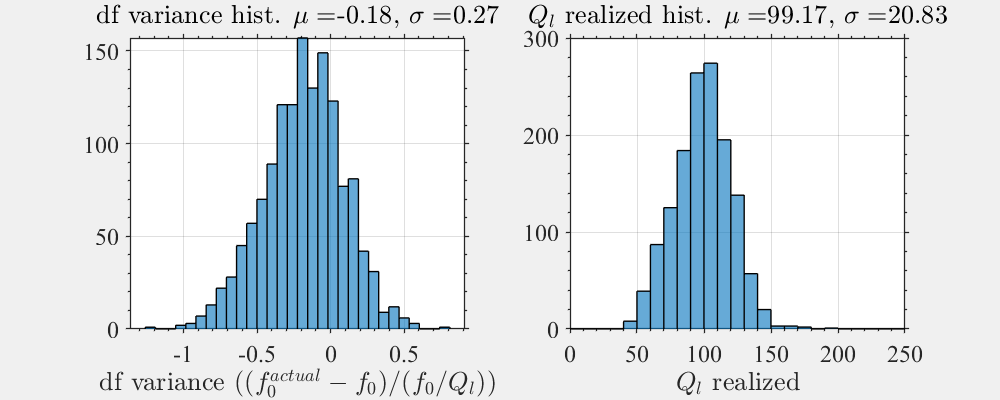

close all; 
clear functions; %#ok<CLFUNC>
n_plot = 1;
showFilterBank(f,Data_dir); 
% showMetrics(f,Ql_target,Data_dir);

Stats_dir = calcStatistics(f0,Ql_target,Data_dir);
showStatistics(f,Data_dir,Stats_dir);

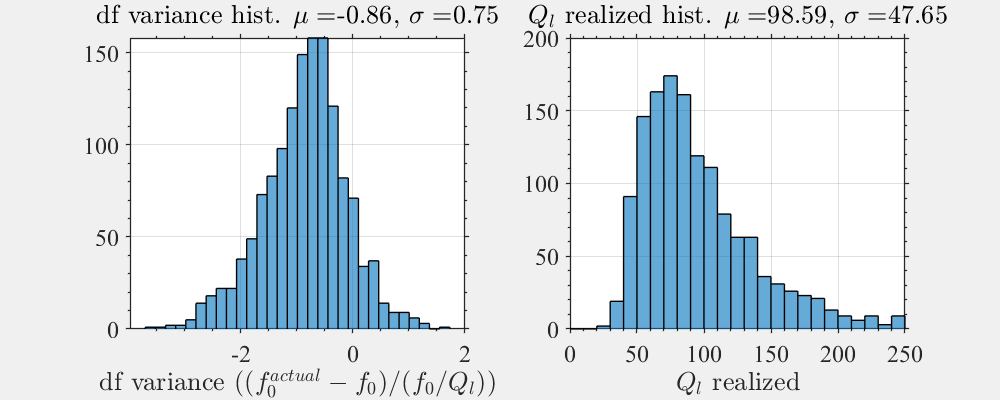


n_plot = 2;
showFilterBank(f,Data_refl);
% showMetrics(f,Ql_target,Data_refl);

Stats_refl = calcStatistics(f0,Ql_target,Data_refl);
showStatistics(f,Data_refl,Stats_refl);

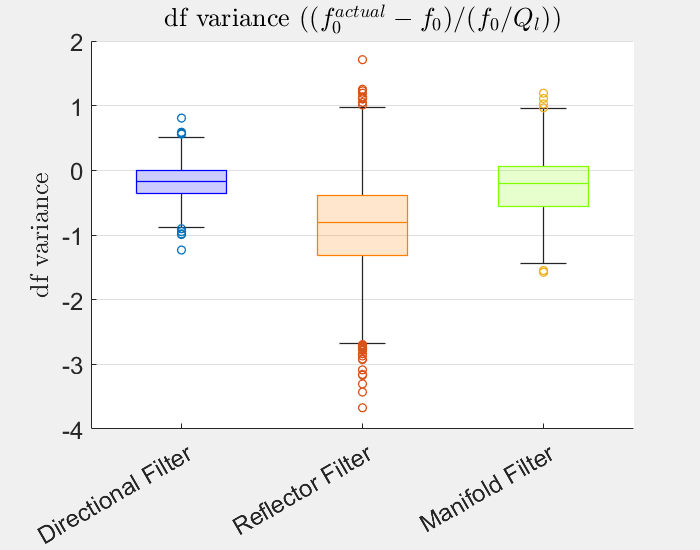

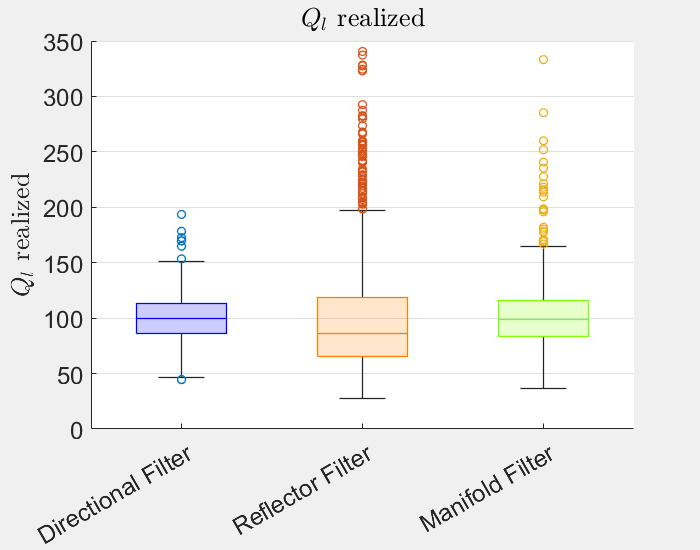

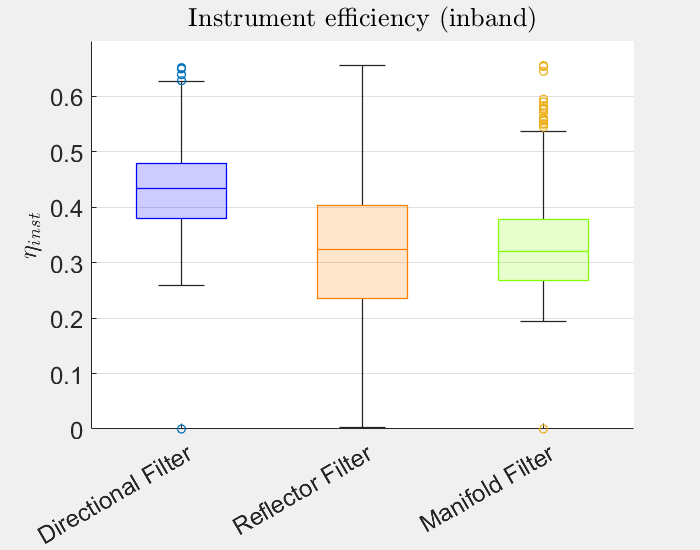

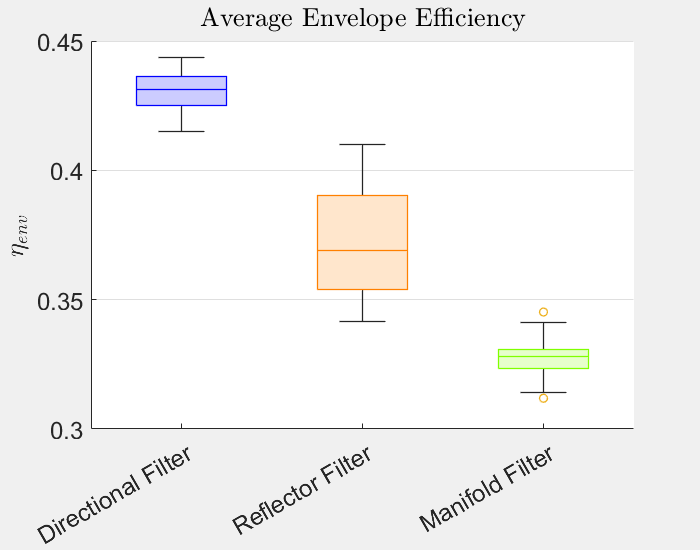

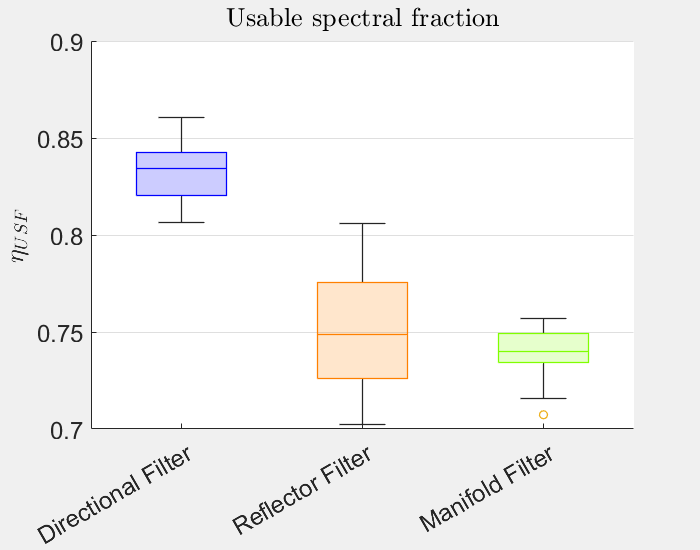

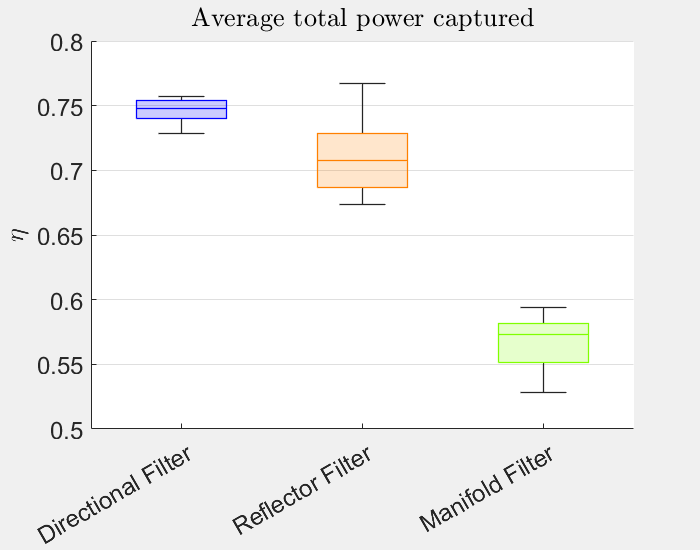

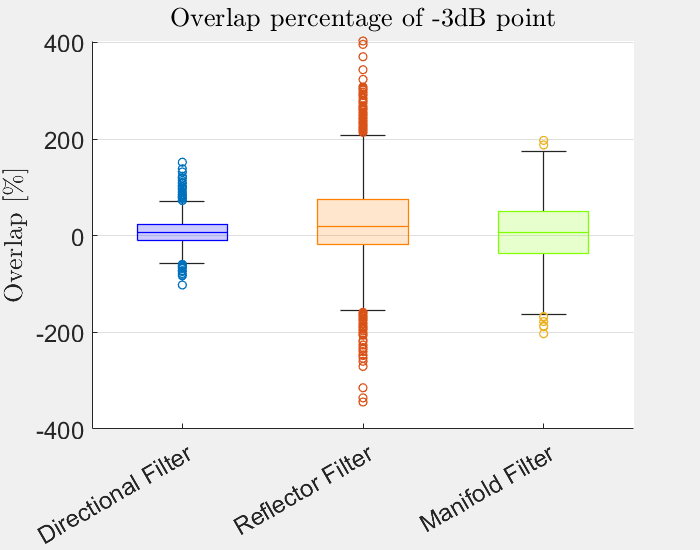

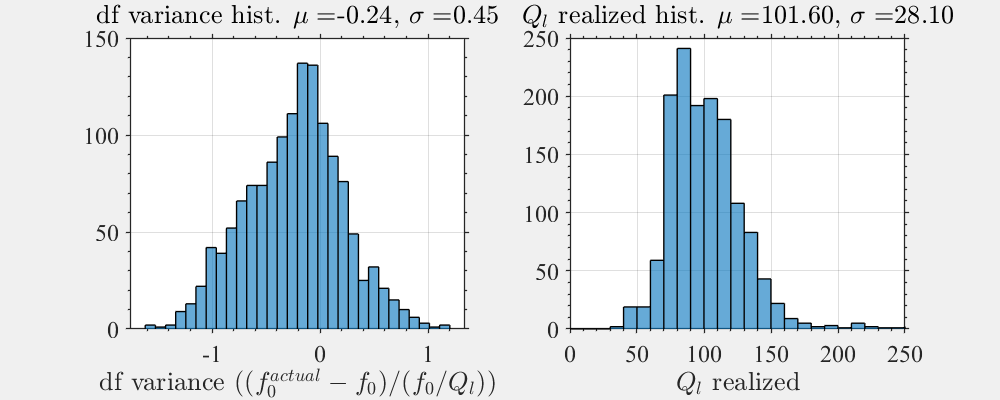



n_plot = 3;
showFilterBank(f,Data_man);
% showMetrics(f,Ql_target,Data_man);

Stats_man = calcStatistics(f0,Ql_target,Data_man);
showStatistics(f,Data_man,Stats_man);

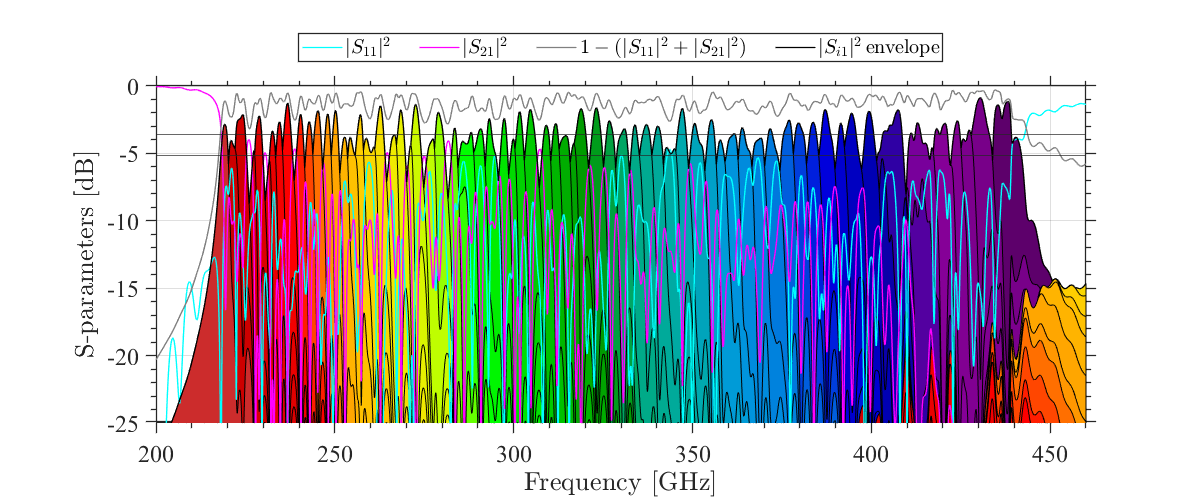

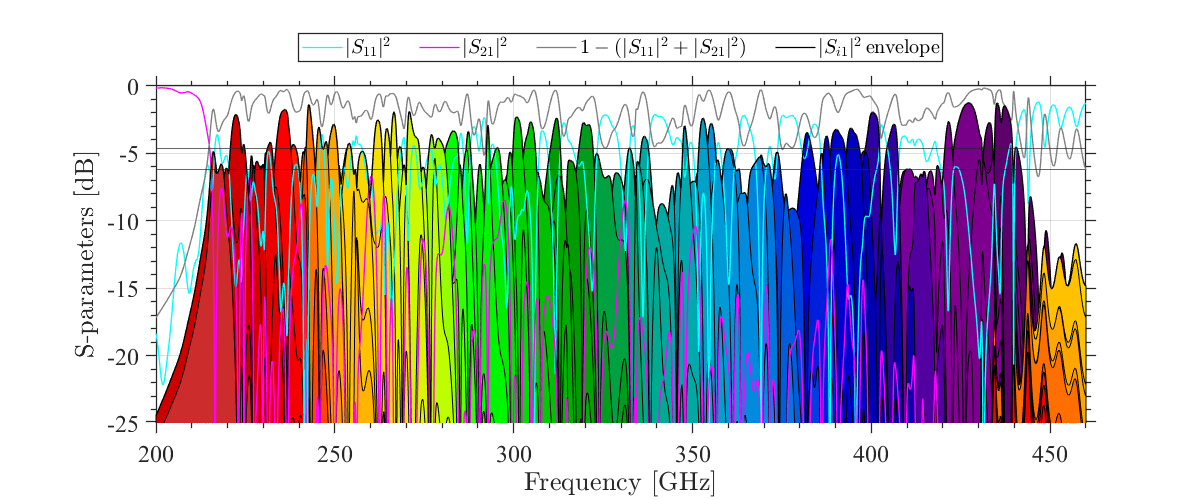

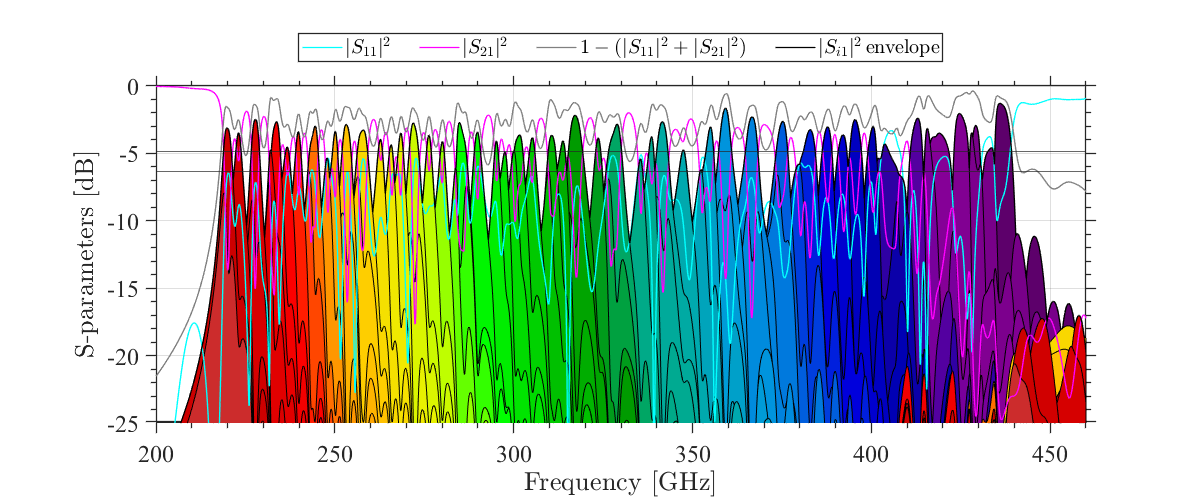



formatPlotting();